# Parameter Estimation of ODE Models for Chemical Kinetics

Parameter estimation or curve fitting is the process of finding the coefficients or parameters to fit some model or curve to a set of data. This module covers how to use MATLAB tools for this process. The specific application features a model consisting of a system of ordinary differential equations for chemical kinetics.

Author: Dr. Ashlee N. Ford Versypt, [ashleefv@buffalo.edu](mailto:ashleefv@buffalo.edu)

Reference: Data, model equations, and expected results figures from [1] M. A. Fahim, T. A. Al-Sahhaf, and A. S. Elkilani. Chapter 8: Fluidised Catalytic Cracking. In Fundamentals of Petroleum Refining, pages 199-235. Elsevier, New York, 2010. [https://doi.org/10.1016/C2009-0-16348-1](https://doi.org/10.1016/C2009-0-16348-1)

## Learning Objectives

By the end of this module, students will be able to:

- use MATLAB functions to estimate parameters for models that involve systems of ordinary differential equations (ODEs) to describe a chemical kinetics problem from the chemical industry

## Problem Statement

Read through the following background and worked solution for estimating the parameters for a three-lump model of the reaction kinetics for a fluid catalytic cracker. Then create your own code for estimating the parameters of a four-lump model of the same application.

### Background

A fluid catalytic cracker or FCC unit (Figure 1) is an industrial process used to convert heavy petroleum refining intermediates into more valuable lighter products via catalytic reactions. The FCC process involves many chemical components and reactions. It is common to gather sets of component chemical species by molecular weight into subgroups referred to as "lumps" instead of considering each component explicitly. 

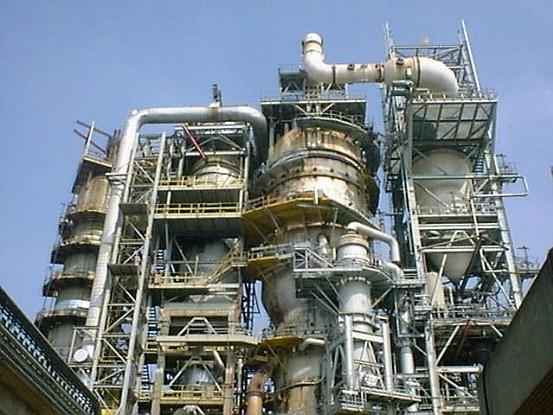

*Figure 1: Fluid catalytic cracker or FCC unit*

Two of the most common kinetic models for the process are called the **three-lump model** and the **four-lump model**.

### Three-lump model

The three-lump model involves three subgroups: VGO ($y_1$), gasoline ($y_2$), and the sum of gas and coke ($y_3$). The reaction network for the three-lump model is shown in Figure 2. The ODEs that define the three-lump model are [1]


$$\frac{dy_1}{dt} = -(k_1+k_3)y_1^2$$



$$\frac{dy_2}{dt} = k_1y_1^2-k_2y_2$$



$$\frac{dy_3}{dt} = k_3y_1^2+k_2y_2$$



$$\frac{dy_1}{dt} = -(k_1+k_3)y_1^2$$


where $k_1$, $k_2$, and $k_3$ are the parameters, and $y_i$ denotes the weight fraction of lump $i$. Conversion is defined as $1-y_i$. Note that the initial conditions are $y_1(0) = 1$, $y_2(0) = 0$, and $y_3(0) = 0$. 

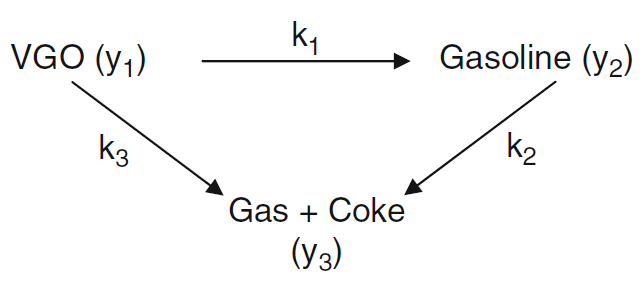

*Figure 2: Three-lump model reaction network [1]*

### Four-lump model

The four-lump model involves four subgroups: VGO ($y_1$), gasoline ($y_2$), gas ($y_3$), and coke ($y_4$). The reaction network for the four-lump model is shown in Figure 3. The ODEs that define the three-lump model are [1]


$$\frac{dy_1}{dt} = -(k_{12}+k_{13}+k_{14})y_1^2$$



$$\frac{dy_2}{dt} = k_{12}y_1^2-k_{23}y_2-k_{24}y_2$$



$$\frac{dy_3}{dt} = k_{13}y_1^2+k_{23}y_2$$



$$\frac{dy_4}{dt} = k_{14}y_1^2+k_{24}y_2$$


where $k_{12}$, $k_{13}$, $k_{14}$, $k_{23}$, and $k_{24}$ are the parameters, and $y_i$ denotes the weight fraction of lump $i$. Conversion is defined as $1-y_i$. Note that the initial conditions are  $y_1(0) = 1$, $y_2(0) = 0$, $y_3(0) = 0$, and $y_4(0) = 0$.

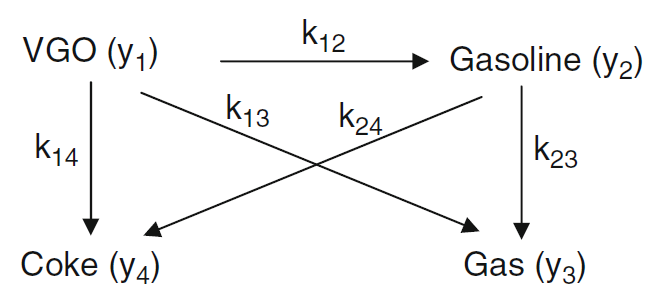

*Figure 3: Four-lump model reaction network [1]*

### Data

The following data have been reported in the literature, summarized in [1], and converted to a convenient form for use here.

*Table 1. Experimental data for the FCC kinetics [1]*

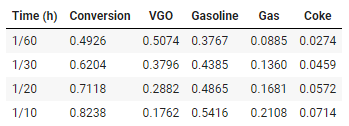

### Expected results

The fitted parameters should yield predicted curves that agree with Figures 4 and 5 from [1]. Some slight deviations are allowable as the parameter estimation procedures in MATLAB differ from those used in the original work [1].

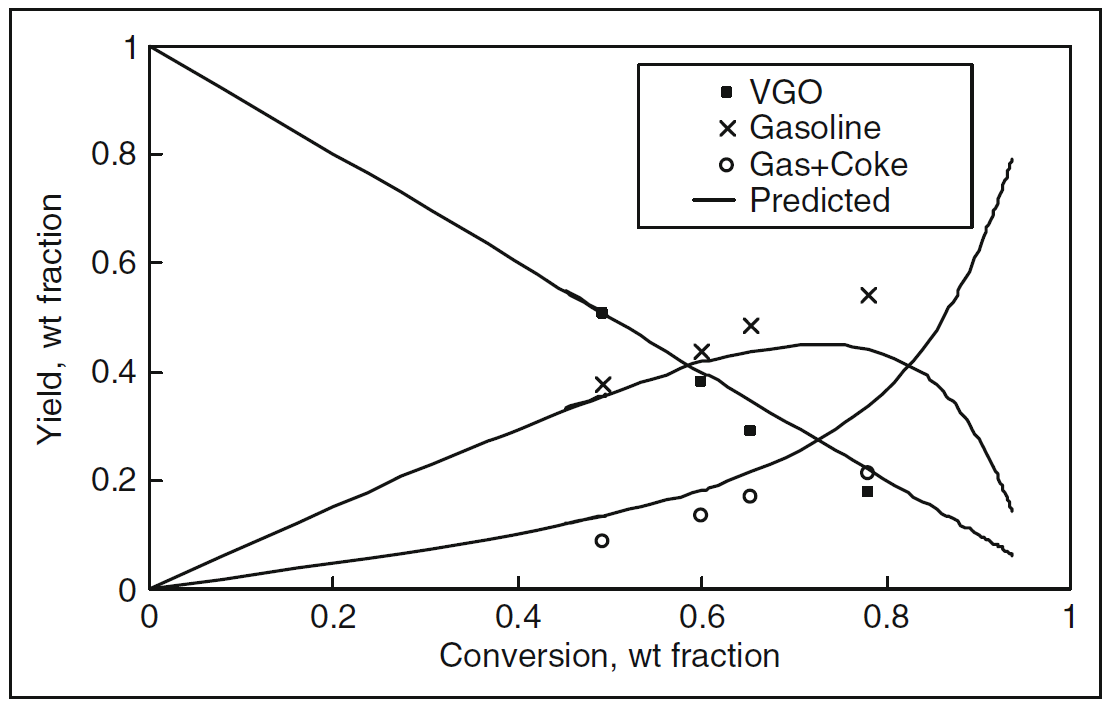

*Figure 4: Data and fitted curve solution for three-lump model [1]*

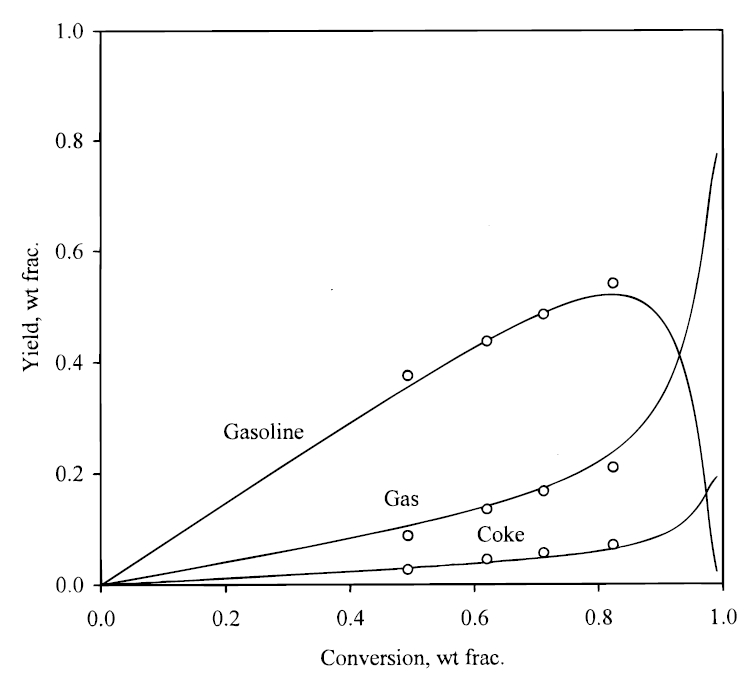

*Figure 5: Data and fitted curve solution for four-lump model [1]*

## Worked Solution for Three-Lump Model

The following worked solution is provided as an example of what is needed to estimate parameters of an ODE model in MATLAB. The codes for user-defined functions in a MATLAB Live Script must be located at the bottom of the script. We have provided links to those codes in the following sections detailing the solution procedures.

### Define the system of ODEs for the three-lump model

We have written a function called `ODEs_3lump` for the three-lump model. This entire function is specific to the system of ODEs for the 3-lump model. If a different model is used, the following list of equations, the y (dependent variable) terms, and the parameters should be updated accordingly.


$$\frac{dy_1}{dt} = -(k_1+k_3)y_1^2$$



$$\frac{dy_2}{dt} = k_1y_1^2-k_2y_2$$



$$\frac{dy_3}{dt} = k_3y_1^2+k_2y_2$$



$$\frac{dy_1}{dt} = -(k_1+k_3)y_1^2$$


with parameters $k_1$, $k_2$, and $k_3$.

### Define model for parameter estimation

The parameter estimation model is the solution to the system of ODEs at specific times corresponding to time points where measurements were taken. We call these `xaxisdata`. We defined the function `model3lump`, which is general for use for any ODE model. However, to use for a new model, users should update the following terms:

- `yaxis0`: one entry for the initial condition for each ODE in order

- `ODEs_3lump`: this is name of the current function that defines the system of ODEs to be solved. If the name of the function changes, it must be updated inside the `ode23` function.

### Data needed for the parameter estimation

The parameter estimation algorithm (`lsqcurvefit` function) needs inputs of the time when measurements were taken (`xaxisData`), the weight fraction data for each lump in the model (`yaxisData`), and initial parameter guesses (for each parameter in the model, packed into a vector called` parameterguesses`). Note that conversion is NOT needed for the parameter estimation process. It is a computed quantity. Experimentally, conversion is $1-y_{1,measured}$where $y_{1,measured}$ is the value of VGO in Table 1. The calculated conversion is $1-y_{1,calculated}$, where $y_{1,calculated}$ is the VGO solution when the estimated parameter values are inserted into the model. The expected results plot the output solutions vs. conversion instead of vs. time. After we solve the model of $y_i$ vs. time, we calculate conversion from the calculated values and then plot $y_i$ vs. conversion.

For a new model, pay close attention that the `yaxisData` corresponds to the measured values for the dependent values of the system of ODEs. Also, there should be one guess for each of the parameters, and the number of these parameters depends on the model (e.g., the 3-lump model has 3 parameters to estimate and thus three guesses are needed:$k_1$, $k_2$, and $k_3$).

% data needed for parameter estimation

% input data from Table 1. Unitless unless otherwise specified
xaxisData = [1/60,1/30,1/20,1/10]; % units of hours
conversionData = [0.4926,0.6204,0.7118,0.8238];
VGOData = [0.5074,0.3796,0.2882,0.1762];
GasolineData = [0.3767,0.4385,0.4865,0.5416];
GasData = [0.0885,0.1360,0.1681,0.2108];
CokeData = [0.0274,0.0459,0.0572,0.0714];

% pack inputs into xdata for curve fitting
yaxisData = [VGOData; GasolineData; GasData + CokeData];

% parameter guesses. Start with all at 1 as a rule of thumb
k1guess = 1;
k2guess = 1;
k3guess = 1;
% pack parameter initial guesses together as a vector for use in lsqcurvefit
parameterguesses = [k1guess, k2guess, k3guess];

## Estimate the parameters using the `lsqcurvefit `built-in function

MATLAB has a built-in function called `lsqcurvefit` to estimate parameters of any user-defined model. Call the function using the data, guesses, and functions previously defined. The function return values are the optimal guesses for each parameter (`parametersoln`) and the residual norm from the curve fitting process (`resnorm`). If another model is used, the `lsqcurvefit` command will need to be updated for the name of the model. Additionally, the names of the estimated parameters and the number of them should be updated when printing the output.

% run lsqcurvefit to estimate parameters
[parametersoln, resnorm] = lsqcurvefit(@(parameterguesses, xaxisData) model3lump(parameterguesses,xaxisData),parameterguesses,xaxisData,yaxisData);


Local minimum possible.
lsqcurvefit stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>



% print outputs
fprintf('Parameter values: \n k_1 = %.4f \n k_2 = %.4f \n k_3 = %.4f \n Residual Norm = %4f \n', parametersoln(1), parametersoln(2), parametersoln(3), resnorm)

Parameter values: 
 k_1 = 38.8368 
 k_2 = 1.8461 
 k_3 = 13.2210 
 Residual Norm = 0.003609 


## Plot kinetic model solutions

To compare our results to the expected results, we create plots of yield vs. time and yield vs. conversion. The first plot, *Figure 6*, shows the weight fraction of each lump over time of the reaction. *Figure 7* shows the weight fraction of each lump at corresponding conversion values (conversion is defined as the amount of VGO consumed in the reaction). Generally, for plotting, we would like smooth curves with many values along the x-axis, many more than that the number of measured data points. So we create a vector called `timeaxisForPlotting` that has a finer time resolution that data points. Note that `yaxis0` needs to match values used in `model3lump` (or in the corresponding name of any new model used). Also, the name `ODE3_lump` should below if the name of the function defining the system of ODEs changes.

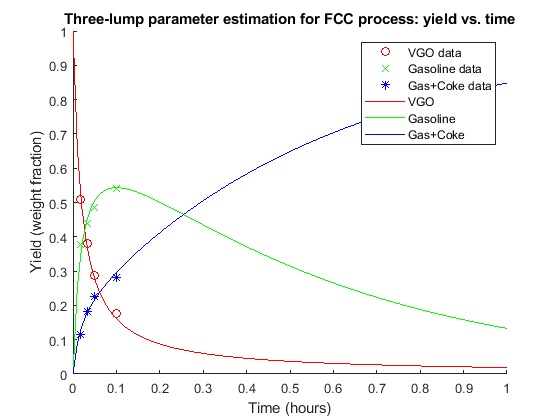

% run the model with estimated parameters for the specified timeaxisForPlotting
   
% initial conditions for the ODEs
y1init = 1;
y2init = 0;
y3init = 0;
yaxis0 = [y1init, y2init, y3init];
timeaxisForPlotting = linspace(0,1,100);
[~, yatsoln] = ode23s(@(t,y) ODEs_3lump(t,y,parametersoln),timeaxisForPlotting,yaxis0);
VGO = yatsoln(:,1);
conversionaxisForPlotting = 1.0-VGO;

% Figure 6: y_i vs. time
figure(6)
hold on
plot(xaxisData,yaxisData(1,:),'ro')
plot(xaxisData,yaxisData(2,:),'gx')
plot(xaxisData,yaxisData(3,:),'b*')
plot(timeaxisForPlotting,yatsoln(:,1),'r')
plot(timeaxisForPlotting,yatsoln(:,2),'g')
plot(timeaxisForPlotting,yatsoln(:,3),'b')
% plot labels: title, axis labels, legend
title('Three-lump parameter estimation for FCC process: yield vs. time')
xlabel('Time (hours)')
ylabel('Yield (weight fraction)')
legend('VGO data','Gasoline data','Gas+Coke data','VGO','Gasoline','Gas+Coke')
hold off

*Figure 6: Three-lump parameter estimation results: yield vs. time*

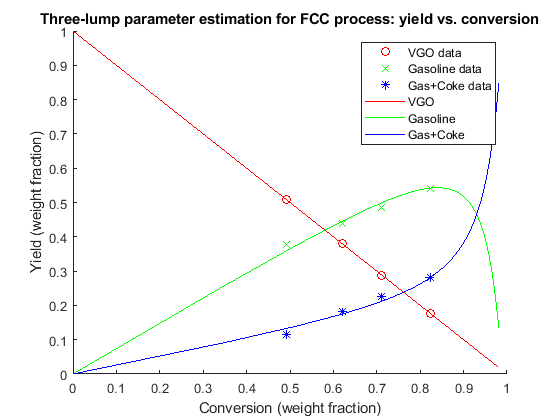

% Figure 7: y_i vs. conversion
figure(7)
hold on
% plotting original data points
plot(conversionData,yaxisData(1,:),'ro')
plot(conversionData,yaxisData(2,:),'gx')
plot(conversionData,yaxisData(3,:),'b*')
plot(conversionaxisForPlotting,yatsoln(:,1),'r')
plot(conversionaxisForPlotting,yatsoln(:,2),'g')
plot(conversionaxisForPlotting,yatsoln(:,3),'b')
% plot labels: title, axis labels, legend
title('Three-lump parameter estimation for FCC process: yield vs. conversion')
xlabel('Conversion (weight fraction)')
ylabel('Yield (weight fraction)')
legend('VGO data','Gasoline data','Gas+Coke data','VGO','Gasoline','Gas+Coke')
hold off

*Figure 7: Three-lump parameter estimation results: yield vs. conversion*

## Your turn!

Adapt the worked solution code above to estimate parameters for the four-lump model. Copy the corresponding codes below, edit accordingly, and solve. Make sure that any user-defined functions are inserted at the bottom of this script.

## Functions

function output = ODEs_3lump(t,y,parameters)
% System of ODEs for three-lump model
    % unpack inputs into variable names
    k1 = parameters(1);
    k2 = parameters(2);
    k3 = parameters(3);
    
    y1 = y(1); % VGO   
    y2 = y(2); % Gasoline
    y3 = y(3); % Gas + Coke

    % define equations for the three-lump model
    dy_dt(1) = -(k1 + k3)* y1^2; %eq 1, weight fraction over time
    dy_dt(2) = k1*y1^2-k2*y2; %eq 2, weight fraction over time
    dy_dt(3) = k3*y1^2+k2*y2; %eq 3, weight fraction over time
    
    % transpose output to properly format for ODE solver
    output = dy_dt';
end

% Model for parameter estimation
function yaxisCalc = model3lump(parameters, xaxisdata)
    % initial conditions for the ODEs
    y1init = 1;
    y2init = 0;
    y3init = 0;
    yaxis0 = [y1init, y2init, y3init];
    yaxisCalc = zeros(length(xaxisdata),length(yaxis0));

    for i = 1:length(xaxisdata) % loop iterates over each entry of time to check solved value at that time point
        if xaxisdata(i) == 0 % if true, output initial condition as answer
            yaxisCalc(i,:) = yaxis0;
        else % if false, solve ODE up to point of t and give solution at t as answer
            xaxisspan = [0, xaxisdata(i)];
            [~, ysoln] = ode23s(@(t,y) ODEs_3lump(t,y,parameters),xaxisspan,yaxis0);
            yaxisCalc(i,:) = ysoln(end,:);
        end
    end
    yaxisCalc = yaxisCalc';
end